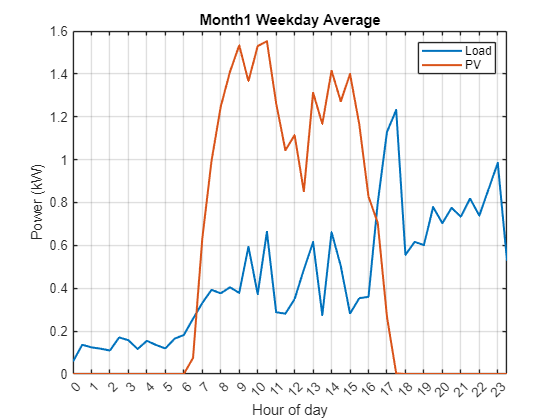

%% CREST monthly averaging from 30 datasets
% Assumes these variables already exist in workspace:
% loaddata1 ... loaddata30
% pvdata1   ... pvdata30
%
% Data structure:
% 1:5    = Month1 weekday (5 sets)
% 6:10   = Month2 weekday (5 sets)
% 11:15  = Month3 weekday (5 sets)
% 16:20  = Month1 weekend (5 sets)
% 21:25  = Month2 weekend (5 sets)
% 26:30  = Month3 weekend (5 sets)
%
% Outputs:
% HalfHourly_Month1_Weekday
% HalfHourly_Month1_Weekend
% HalfHourly_Month1_FullWeek
% HalfHourly_Month2_Weekday
% HalfHourly_Month2_Weekend
% HalfHourly_Month2_FullWeek
% HalfHourly_Month3_Weekday
% HalfHourly_Month3_Weekend
% HalfHourly_Month3_FullWeek
%
% Total averages across all months:
% HalfHourly_Weekday
% HalfHourly_Weekend
% HalfHourly

clearvars -except loaddata* pvdata*

%% Settings
blk = 30;   % 30 samples per half-hour block

%% Helper function: convert one raw dataset to 48 half-hour averages
get48 = @(x) mean(reshape(x(1:floor(numel(x)/blk)*blk), blk, []), 1).';

%% Preallocate
LoadAll48 = zeros(48,30);
PVAll48   = zeros(48,30);

%% Convert all 30 datasets to 48-point daily profiles
for k = 1:30
    ld = eval(sprintf('loaddata%d{:,1};', k));
    pv = eval(sprintf('pvdata%d{:,1};', k));

    LoadAll48(:,k) = get48(ld);
    PVAll48(:,k)   = get48(pv);
end

%% Half-hour axis
HalfHour = (0:47).' / 2;

%% Index groups

% Weekdays
idx_month1_weekday = 1:5;
idx_month2_weekday = 6:10;
idx_month3_weekday = 11:15;

% Weekends
idx_month1_weekend = 16:20;
idx_month2_weekend = 21:25;
idx_month3_weekend = 26:30;

% Totals
idx_all_weekday = 1:15;
idx_all_weekend = 16:30;

%% ---------- Month1 ----------
% Weekday average
Load48 = mean(LoadAll48(:,idx_month1_weekday), 2);
PV48   = mean(PVAll48(:,idx_month1_weekday), 2);
HalfHourly_Month1_Weekday = table(HalfHour, Load48, PV48);

% Weekend average
Load48 = mean(LoadAll48(:,idx_month1_weekend), 2);
PV48   = mean(PVAll48(:,idx_month1_weekend), 2);
HalfHourly_Month1_Weekend = table(HalfHour, Load48, PV48);

% Full-week average
Load48 = (5*HalfHourly_Month1_Weekday.Load48 + 2*HalfHourly_Month1_Weekend.Load48)/7;
PV48   = (5*HalfHourly_Month1_Weekday.PV48   + 2*HalfHourly_Month1_Weekend.PV48)/7;
HalfHourly_Month1_FullWeek = table(HalfHour, Load48, PV48);

%% ---------- Month2 ----------
% Weekday average
Load48 = mean(LoadAll48(:,idx_month2_weekday), 2);
PV48   = mean(PVAll48(:,idx_month2_weekday), 2);
HalfHourly_Month2_Weekday = table(HalfHour, Load48, PV48);

% Weekend average
Load48 = mean(LoadAll48(:,idx_month2_weekend), 2);
PV48   = mean(PVAll48(:,idx_month2_weekend), 2);
HalfHourly_Month2_Weekend = table(HalfHour, Load48, PV48);

% Full-week average
Load48 = (5*HalfHourly_Month2_Weekday.Load48 + 2*HalfHourly_Month2_Weekend.Load48)/7;
PV48   = (5*HalfHourly_Month2_Weekday.PV48   + 2*HalfHourly_Month2_Weekend.PV48)/7;
HalfHourly_Month2_FullWeek = table(HalfHour, Load48, PV48);

%% ---------- Month3 ----------
% Weekday average
Load48 = mean(LoadAll48(:,idx_month3_weekday), 2);
PV48   = mean(PVAll48(:,idx_month3_weekday), 2);
HalfHourly_Month3_Weekday = table(HalfHour, Load48, PV48);

% Weekend average
Load48 = mean(LoadAll48(:,idx_month3_weekend), 2);
PV48   = mean(PVAll48(:,idx_month3_weekend), 2);
HalfHourly_Month3_Weekend = table(HalfHour, Load48, PV48);

% Full-week average
Load48 = (5*HalfHourly_Month3_Weekday.Load48 + 2*HalfHourly_Month3_Weekend.Load48)/7;
PV48   = (5*HalfHourly_Month3_Weekday.PV48   + 2*HalfHourly_Month3_Weekend.PV48)/7;
HalfHourly_Month3_FullWeek = table(HalfHour, Load48, PV48);

%% ---------- Overall totals across all months ----------
% Total weekday average across all weekday sets
Load48 = mean(LoadAll48(:,idx_all_weekday), 2);
PV48   = mean(PVAll48(:,idx_all_weekday), 2);
HalfHourly_Weekday = table(HalfHour, Load48, PV48);

% Total weekend average across all weekend sets
Load48 = mean(LoadAll48(:,idx_all_weekend), 2);
PV48   = mean(PVAll48(:,idx_all_weekend), 2);
HalfHourly_Weekend = table(HalfHour, Load48, PV48);

% Total full-week average across all months
Load48 = (5*HalfHourly_Weekday.Load48 + 2*HalfHourly_Weekend.Load48)/7;
PV48   = (5*HalfHourly_Weekday.PV48   + 2*HalfHourly_Weekend.PV48)/7;
HalfHourly = table(HalfHour, Load48, PV48);

%% ---------- Plots ----------
% Month1
figure;
plot(HalfHourly_Month1_Weekday.HalfHour, ...
    [HalfHourly_Month1_Weekday.Load48 HalfHourly_Month1_Weekday.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month1 Weekday Average');
legend({'Load','PV'}, 'Location','northeast');

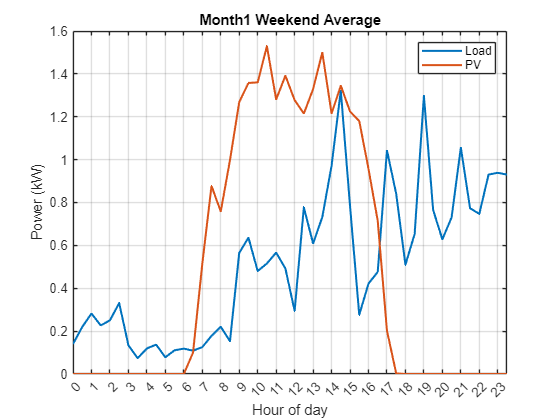


figure;
plot(HalfHourly_Month1_Weekend.HalfHour, ...
    [HalfHourly_Month1_Weekend.Load48 HalfHourly_Month1_Weekend.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month1 Weekend Average');
legend({'Load','PV'}, 'Location','northeast');

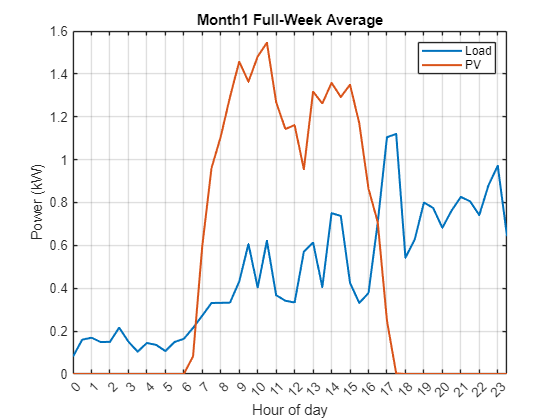


figure;
plot(HalfHourly_Month1_FullWeek.HalfHour, ...
    [HalfHourly_Month1_FullWeek.Load48 HalfHourly_Month1_FullWeek.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month1 Full-Week Average');
legend({'Load','PV'}, 'Location','northeast');

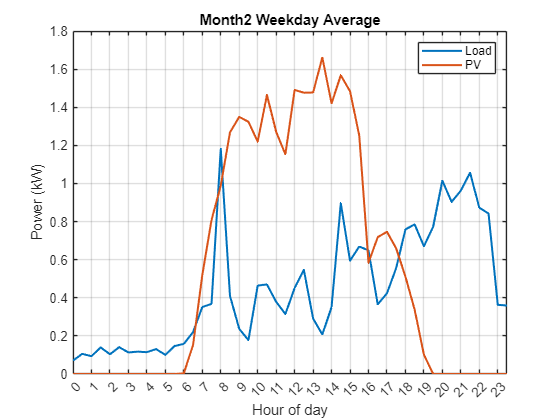


% Month2
figure;
plot(HalfHourly_Month2_Weekday.HalfHour, ...
    [HalfHourly_Month2_Weekday.Load48 HalfHourly_Month2_Weekday.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month2 Weekday Average');
legend({'Load','PV'}, 'Location','northeast');

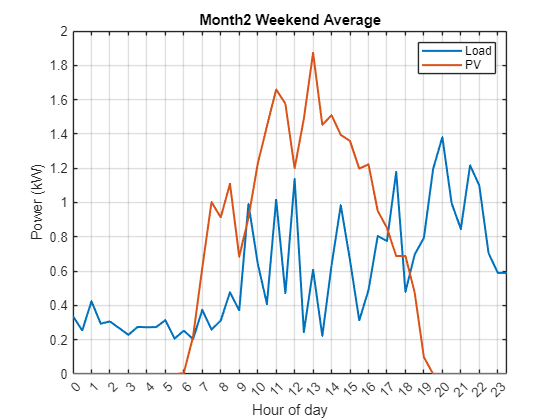


figure;
plot(HalfHourly_Month2_Weekend.HalfHour, ...
    [HalfHourly_Month2_Weekend.Load48 HalfHourly_Month2_Weekend.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month2 Weekend Average');
legend({'Load','PV'}, 'Location','northeast');

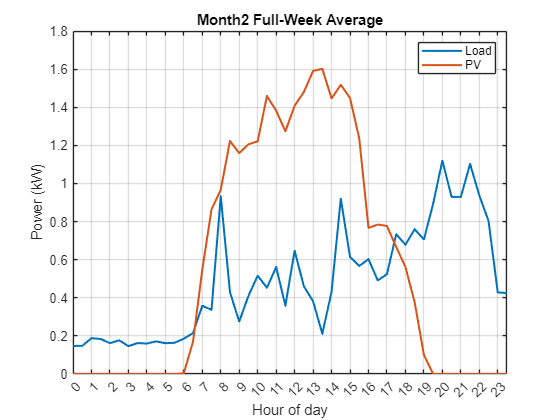


figure;
plot(HalfHourly_Month2_FullWeek.HalfHour, ...
    [HalfHourly_Month2_FullWeek.Load48 HalfHourly_Month2_FullWeek.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month2 Full-Week Average');
legend({'Load','PV'}, 'Location','northeast');

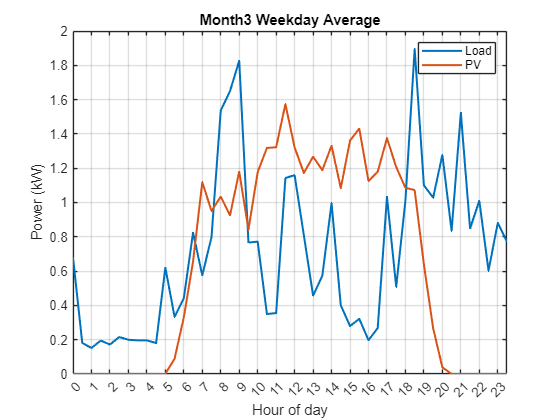


% Month3
figure;
plot(HalfHourly_Month3_Weekday.HalfHour, ...
    [HalfHourly_Month3_Weekday.Load48 HalfHourly_Month3_Weekday.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month3 Weekday Average');
legend({'Load','PV'}, 'Location','northeast');

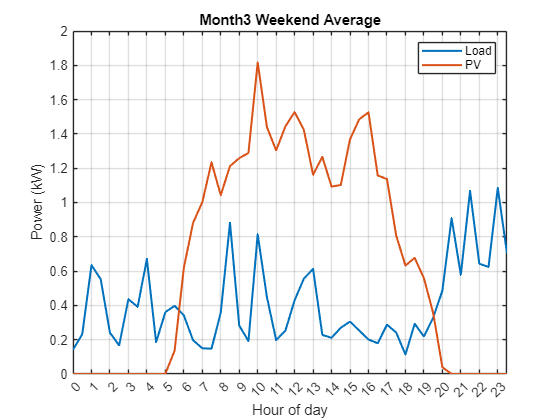


figure;
plot(HalfHourly_Month3_Weekend.HalfHour, ...
    [HalfHourly_Month3_Weekend.Load48 HalfHourly_Month3_Weekend.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month3 Weekend Average');
legend({'Load','PV'}, 'Location','northeast');

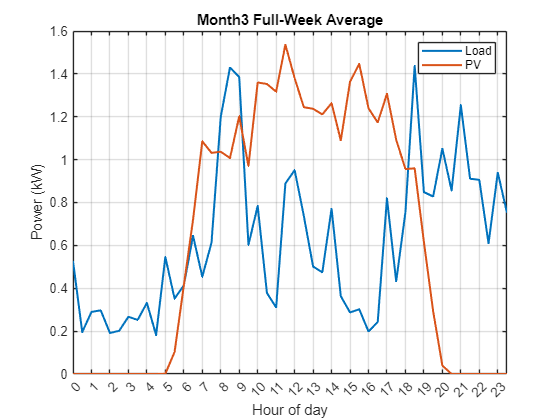


figure;
plot(HalfHourly_Month3_FullWeek.HalfHour, ...
    [HalfHourly_Month3_FullWeek.Load48 HalfHourly_Month3_FullWeek.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Month3 Full-Week Average');
legend({'Load','PV'}, 'Location','northeast');

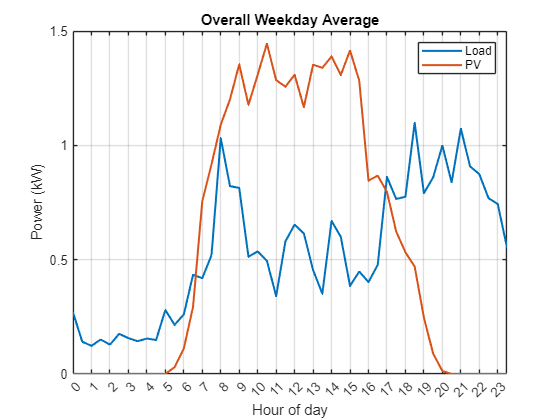


% Overall totals
figure;
plot(HalfHourly_Weekday.HalfHour, ...
    [HalfHourly_Weekday.Load48 HalfHourly_Weekday.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Overall Weekday Average');
legend({'Load','PV'}, 'Location','northeast');

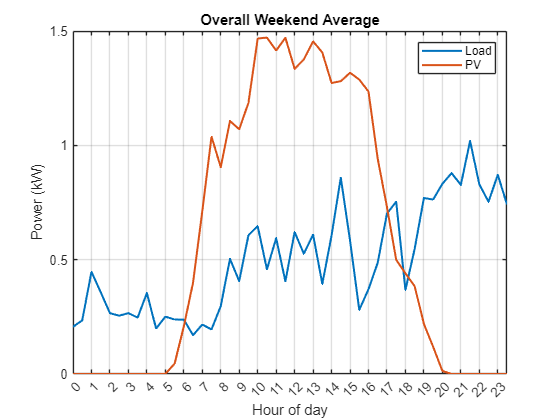


figure;
plot(HalfHourly_Weekend.HalfHour, ...
    [HalfHourly_Weekend.Load48 HalfHourly_Weekend.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Overall Weekend Average');
legend({'Load','PV'}, 'Location','northeast');

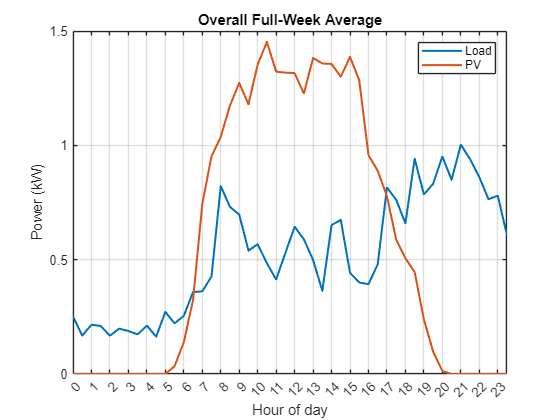


figure;
plot(HalfHourly.HalfHour, [HalfHourly.Load48 HalfHourly.PV48], 'LineWidth', 1.5);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Overall Full-Week Average');
legend({'Load','PV'}, 'Location','northeast');